# VectorsAndRotations

This script illustrates MATLAB functions which compute the 3d-cartesian vector inner product and cross product of vector, and a wide variety of functions used to express rotations of vectors and of parametric surfaces. 

Author: D. Carlsmith

clear all;close all

### Vectors of symbols and  inner and cross products

***Try this***: Read about the [cross product](https://en.wikipedia.org/wiki/Cross_product) .

It is handy to work with vectors containing MATLAB symbolic variables and to generate component names that have subscripts using [sym](https://www.mathworks.com/help/symbolic/sym.html) (not [syms](https://www.mathworks.com/help/symbolic/syms.html)) .  See [https://www.mathworks.com/matlabcentral/answers/2521-creating-vector-of-symbols](https://www.mathworks.com/matlabcentral/answers/2521-creating-vector-of-symbols) for how to autogenerate vector component symbols with subscripts appended to vector name (A(1) = A1...) using a construct like A%d or A_%d to and how to make matrices of symbols, useful for symbolic computations. The Live Script environment reinterprets these to show subscripts but you refer to the elements by index into the array, eg the first one is `A(1)`, not `A_1`. Let's make two generic vectors to play with.

A=sym('A_%d', [1 3]), B=sym('B%d', [1 3])

$$A = \left(\begin{array}{ccc} A_{1} & A_{2} & A_{3} \end{array}\right)$$

$$B = \left(\begin{array}{ccc} B_{1} & B_{2} & B_{3} \end{array}\right)$$

Now we can illustrate symbolically the MATLAB definitions of the inner ([dot](https://www.mathworks.com/help/matlab/ref/dot.html)) product and [cross](https://www.mathworks.com/help/matlab/ref/cross.html) product.

C=dot(A,B), D=cross(A,B)

$$C = B_{1}\,\bar{A_{1}}+B_{2}\,\bar{A_{2}}+B_{3}\,\bar{A_{3}}$$

$$D = \left(\begin{array}{ccc} A_{2}\,B_{3}-A_{3}\,B_{2} & A_{3}\,B_{1}-A_{1}\,B_{3} & A_{1}\,B_{2}-A_{2}\,B_{1} \end{array}\right)$$

Note the overbar denotes complex conjugate and applies to complex number components.

### Vectors and rotations

A 1-dimensional array/vector need have no geometrical interpretation in general. However, the set of all 3-component vectors of real numbers corresponds to the cartesian components of displacement vectors in 3d Euclidean space. With this correspondance, we  can make the interpretation ${\bf A}\cdot{\bf B} = {\bf A}|{\bf B}|\cos\theta_{AB}$ and ${\bf A}\times{\bf B}=|{\bf A}||{\bf B}|\sin\theta_{AB}{\bf n}$ where ${\bf n}$ is a unit vector normal to ${\bf A}$ and to ${\bf B}$ in the direction given by the right-hand-rule and $\theta_{AB}$ the angle between the two vectors. We will discover matrices that correspond to rotations of the vectors or of the cordinate system such that if the component values of a vector ${\bf A}$ are $A_i$ in one frame of reference and $A_i'$ relative to a rotated frame, then the components are related by a linear matrix transormation $A'=MA$where $M$ is a  rotation matrix that depends on the frame orientations alone. In physics, a vector equation like


$${\bf F} = m{\bf a}$$


has the component forms in two frame of reference

$F = ma$ and $F'= m a'.$ Since $F'=MF$ and $a'=Ma$, multiplying $F=ma$ by $M$ gives the 2nd equation. The general law in vector form applies in all frames even though the values of the components depend upon the orientation of the frame. The values are relative quantities.

It is not obvious but can be shown that  the cross product ${\bf A}\times{\bf B}$ of vectors  is a vector in the sense that it behaves like ${\bf A}$and ${\bf B}$ under rotations, i.e. a rotation of a cross product vector is the same as the cross product of the rotated vectors. We explore that below by example.

***Try this: ***Check that dot(A,B)=dot(B,A) (for real vectors) and that cross(A,B)=-cross(B,A).

### Numerical vectors and computations

Define two 3d column vectors `V` and `W` with random components within the postive quadrant of a unit cube using [rand](https://www.mathworks.com/help/matlab/ref/rand.html).

V = rand(3,1), W=rand(3,1)

V =     0.0975
    0.2785
    0.5469


W =     0.9575
    0.9649
    0.1576


***Try this***: Rerun this section to generate different random vectors. Note the vectors are not necessarily unit length.

Compute their inner (dot) product using the MATLAB `dot `command.

VdotW= dot(V,W)

VdotW = 0.4483

**Try this**: Check in the command window that `WdotV = dot(W,V) `is equal to VdotW=dot(V,W). See definition above to verify this must be true.

Compute the magnitudes of the vectors using[ norm](https://www.mathworks.com/help/matlab/ref/norm.html).

Vmag= norm(V),Wmag=norm(W)

Vmag = 0.6214

Wmag = 1.3685

***Try this***: Compute the magnitudes of the vectors using e.g. `sqrt(dot(V,V)),  sqrt(V'*V),  or sqrt(sum(V.*V)) in the comand window` and compare to` norm(V)`.

%V=[1;0;0];W=[0;1;0]

***Try this***: Change from random vectors to unit vectors, such as $\hat{\bf x}$ and $\hat{\bf y}$ or  $\hat{\bf x}$ and $\hat{\bf z}$, or to your own choice vectors, by uncommenting and altering as needed the previous  line, overriding the random vector component values.

Compute the cross product with the MATLAB `cross` command. 

Z=cross(V,W)

Z =    -0.4838
    0.5083
   -0.1725


***Try this***: Compute in the command window the cross product of the [transposed ](https://www.mathworks.com/help/matlab/ref/transpose.html)vectors,` Z_try=cross(V',W')`. Does this give an error, the transpose of the original cross product, or the same row or column vector as `Z=cross(V,W)`?

### Convert between Cartesian and angular variables

Convert a vector to [polar coordinates](https://en.wikipedia.org/wiki/Polar_coordinate_system) using MATLAB's [cart2pol](https://www.mathworks.com/help/matlab/ref/cart2pol.html) command. 

[Vphi, Vrho, Vz]   = cart2pol(V(1),V(2),V(3)) 

Vphi = 1.2339

Vrho = 0.2951

Vz = 0.5469

***Try this***: Is the z-component the same in the polar coordinate system as in the cartesian system? Does the polar angle make sense?

Convert to [spherical coordinates](https://en.wikipedia.org/wiki/Spherical_coordinate_system) using the MATLAB [cart2sph](https://www.mathworks.com/help/matlab/ref/cart2sph.html) command.

**Warning**: MATLAB returns elevation angle $\theta$ (measured from x-y plane in the positive z-direction) used in e.g. aerodynamics, not the polar angle $\theta$ (measured from the positive z-axis) as is ubiquitous in physics.

[Vphi, Vtheta, Vr] = cart2sph(V(1),V(2),V(3))

Vphi = 1.2339

Vtheta = 1.0760

Vr = 0.6214

***Try this***: `Vr` should be the length of the vector. Compute in the command window `vmag=sqrt(dot(V,V))`. Is `vmag=Vr`?

Convert angles in radians to degrees with [rad2deg](https://www.mathworks.com/help/matlab/ref/rad2deg.html).

VphiD = rad2deg(Vphi)

VphiD = 70.6979

VthetaD = rad2deg(Vtheta)

VthetaD = 61.6497

***Try this***: Look at the display of the vectors below. Do these angles make sense? Is it true that V`theta= pi/2-acos( dot(V,[0;0;1])/sqrt(dot(V,V)) )`? (Convince yourself this should be true.)

### Rotation matrices

The effect of a rotation on a 3-vector can be represented by a matrix such that the columar components of the rotated vector are equal to those obtained by multiplying the column vector on the left by the matrix.

Create copies of the vectors that are rotated about the z-axis by 90 degrees. Notice the structure of the rotation matrix `Rz` below and convince yourself that the vector `Rz*V `obtained using a matrix multiplication gives the components of the rotated vector.

thetad=90;                              % an angle in degrees
theta=deg2rad(thetad);                  % the same angle in radians
Rz=[cos(theta), -sin(theta), 0;...
   +sin(theta), cos(theta), 0;...
             0,          0, 1];
Rx=[1,           0,          0;...
      0, cos(theta), -sin(theta);...
      0, +sin(theta), cos(theta)];
VR=Rz*V;WR=Rz*W;ZR=Rz*Z;                % rotated vectors

MATLAB offers rotation matriix generation commands [rotx](https://www.mathworks.com/help/phased/ref/rotx.html), `roty`, and `rotz`. Compare the matrix for rotation about the x-axis that we have constructed with one constructed using MATLAB's `rotx` command.

R0=Rx

R0 =     1.0000         0         0
         0    0.0000   -1.0000
         0    1.0000    0.0000


Since our matrix was built with finite precision, some elements are inexact. We can rectify this to an extent by setting to zero elements consistent with zero within the floating point accuracy [eps](https://www.mathworks.com/help/matlab/ref/eps.html).

Rx(abs(Rx)<eps)=0;
R0=Rx

R0 =      1     0     0
     0     0    -1
     0     1     0


R1=rotx(thetad)

R1 =      1     0     0
     0     0    -1
     0     1     0


Note: The active form of a rotation above rotates the vector relative to a fixed coordinate system and is equivalent to a passive rotation of the coordinate system in the opposite sense (with reversed angle).

***Try this***: Switch from vectors rotated about the z-axis to vectors rotated, say, about the x-axis by an angle $\theta$, or to a similar Ry matrix for the y-axis. Does the rotation work as expected in the graphical display below? As a quick check, set ${\bf V}=\hat{\bf x}$ above. What is RzV in that case?

***Try this***: Replace `Rz `with` Rz^2 = Rz*Rz `in creating the rotated vectors above`. `Does the rotation angle double in the graphical display below?

***Try this***: Does the order of rotaion about different axes matter? For example, does `Rz*Rx=Rx*Rz `mathematically and hence in effect`.`

***Try this:***  Compute in the command window the cross product of the rotated vectors, `cross(VR,WR)`. Is this equal to the rotated vector `Z,` i.e. to the vector obtained by rotating the cross product of `V `and `W`?

***Try this***:  Why is there an apparent sign difference between the angles in the expression for `roty` in comparision to `rotx `and `rotz`? 

### Impact of rotations on inner and vector products

Compute the inner products of the 3 vectors V, W, and Z=cross(V,W).

dot(Z,W)

ans = -5.5511e-17

dot(Z,V)

ans = 1.3878e-17

dot(V,W)

ans = 0.4483

***Try this:  ***Now compute the same inner products but using rotated vectors `RV`, `RW`, and `RZ.` Are the corresponding inner products equal?

### Graphical display of vectors

Plot each vector as a line from the origin using [quiver3](https://www.mathworks.com/help/matlab/ref/quiver3.html).

figure(1)
scale=0; % This value tells quiver3 to not scale down the length.
quiver3(0,0,0,V(1),V(2),V(3),scale,'r','linewidth',2)
hold on
quiver3(0,0,0,W(1),W(2),W(3),scale,'b','linewidth',2)
quiver3(0,0,0,Z(1),Z(2),Z(3),scale,'g','linewidth',2)

Label the vectors using [text](https://www.mathworks.com/help/matlab/ref/text.html).

set(gca,'fontsize',14);
text(V(1),V(2),V(3),'{\bf V}')
text(W(1),W(2),W(3),'{\bf W}')
text(Z(1),Z(2),Z(3),'{\bf Z}={\bf V}\times{\bf W}')

Plot Cartesian vector components for the first vector in the same color but with dashed lines.

quiver3(0,0,0,V(1),0,0,scale,'r--','linewidth',2)
quiver3(0,0,0,0,V(2),0,scale,'r--','linewidth',2)
quiver3(0,0,0,0,0,V(3),scale,'r--','linewidth',2)

Show dashed projection lines for the first vector.

quiver3(V(1),0,0,0,V(2),V(3),scale,'--')
quiver3(0,V(2),0,V(1),0,V(3),scale,'--')
quiver3(0,0,V(3),V(1),V(2),0,scale,'--')

Add rotated vectors.

quiver3(0,0,0,VR(1),VR(2),VR(3),scale,'r','linewidth',2)
quiver3(0,0,0,WR(1),WR(2),WR(3),scale,'b','linewidth',2)
quiver3(0,0,0,ZR(1),ZR(2),ZR(3),scale,'g','linewidth',2)
text(VR(1),VR(2),VR(3),'{\bf VR}')
text(WR(1),WR(2),WR(3),'{\bf WR}')
text(ZR(1),ZR(2),ZR(3),'{\bf ZR}={\bf VR}\times{\bf WR}')

xlabel('x');ylabel('y');zlabel('z')
grid on

Set plot box aspect ratios all equal with [pbaspect](https://www.mathworks.com/help/matlab/ref/pbaspect.html). (See too [daspect](https://www.mathworks.com/help/matlab/ref/daspect.html ).)

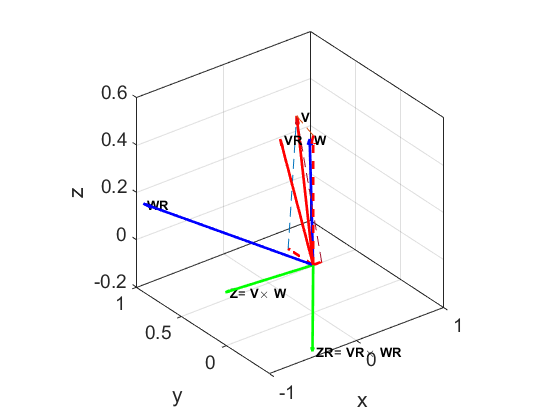

pbaspect([1 1 1]) 
box on
hold off

***Try this:*** Rotate the 3d graphic display interactively using its twirl tool. Convince yourself the vector product of ${\bf V}$ and ${\bf W}$ is orthogonal to both ${\bf V}$ and ${\bf W}$. Try interchanging ${\bf V}$ and ${\bf W}$ in the definition of ${\bf Z}$. Does the resulting vector change sign? 

### Properties of rotation matrices

Rotation matrices are [orthogonal](https://en.wikipedia.org/wiki/Orthogonal_matrix) matrices, a subset of all 3x3 real matrices. The [transpose](https://en.wikipedia.org/wiki/Transpose) of an orthogonal matrix `R` is also its [inverse](https://en.wikipedia.org/wiki/Invertible_matrix) (and represents the reverse rotation) and the determinant of `R` is 1. 

***Try this***: Read about the [determinant](https://en.wikipedia.org/wiki/Determinant)  .

**Try this**: What products of rotations should result in a unit matrix?

A matrix for a rotation by an angle $t$ about a unit vector $\hat{\bf n}=[u,v,w]=[\cos \phi\sin\theta ,\sin\phi\sin\theta ,\cos\theta]$ has the form defined below. Here, $\theta$ and $\phi$ are the polar angle and azimuthal angle in spherical coordinates.

syms u v w t theta phi
assume([u,v,w,t,theta,phi],'real')
u=cos(phi)*sin(theta);v=sin(phi)*sin(theta);w=cos(theta);
A = [ cos(t) + u^2*(1-cos(t)), u*v*(1-cos(t)) + w*sin(t), w*u*(1-cos(t)) - v*sin(t); ...
    u*v*(1-cos(t)) - w*sin(t), cos(t) + v^2*(1-cos(t)), v*w*(1-cos(t)) + u*sin(t); ...
    w*u*(1-cos(t)) + v*sin(t), v*w*(1-cos(t)) - u*sin(t), cos(t) + w^2*(1-cos(t)) ] ;

Verify that the matrix is orthogonal by computing the determinant and checking the transpose is the inverse.

simplify(det(A))

$$ans = 1$$

simplify(A*A')

$$ans = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

***Try this***: Examine the previous quantities `det(A)` and `A*A'` in the command window without the simplify step.

Show that for the matrix has no effect on a vector proportional to $\bf n$ by showing it converts ${\bf n}$ into itself.

simplify(A*[u;v;w])

$$ans = \left(\begin{array}{c} \cos\left(\varphi \right)\,\sin\left(\theta \right)\\ \sin\left(\varphi \right)\,\sin\left(\theta \right)\\ \cos\left(\theta \right) \end{array}\right)$$

Find the effect of a rotation by 180 degrees about the z-axis on a unit vector along the x-axis.

subs(A,[theta,phi,t],[0,0,pi/2])*[1;0;0]

$$ans = \left(\begin{array}{c} 0\\ -1\\ 0 \end{array}\right)$$

***Try this***: By altering the next line, find the vector obtained by rotating ${\hat{\bf x}}$ by 30 degrees about a direction ${\bf n} = [1,1,1]/\sqrt{3}$.

double(subs(A,[theta,phi,t],[pi/4,pi/4,pi/6])*[0;1;0])

ans =     0.3870
    0.8995
   -0.2026


### Rotations of parametric surfaces

The following derives from the mathworks example on [rotation matrix and trnasformation matrix](http:// https://www.mathworks.com/help/symbolic/examples/rotation-matrix-and-transformation-matrix.html ).  

Define a [parametric surface](https://en.wikipedia.org/wiki/Parametric_surface) `x(u,v)`, `y(u,v)`, `z(u,v)`.

***Try this***: Change paramters a, b, c, d below (e.g. set c=2) to discover interesting surfaces. Can you imagine what they are before plotting them?

syms u v
syms a b c d
a=1;b=1;c=1;d=1;

x = cos(a*u)*sin(b*v);
y = sin(a*u)*sin(b*v);
z = cos(d*v)*sin(d*v);

Plot the surface using [fsurf](https://www.mathworks.com/help/matlab/ref/fsurf.html). 

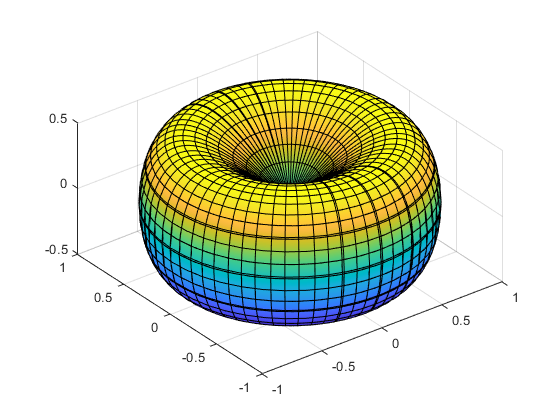

fsurf(x,y,z)
daspect([1 1 1])

Create 3-by-3 matrices `Rx`, `Ry`, and `Rz` representing plane rotations by an angle `t` about the `x`-, `y`-, and `z`-axis, respectively. Note: rotx will not accept a symbolic argument so we build rotation matrices by hand.

syms t

Rx = [1 0 0;...
      0 cos(t) -sin(t);...
      0 sin(t) cos(t)];
Ry = [cos(t) 0 sin(t); 0 1 0; -sin(t) 0 cos(t)];
Rz = [cos(t) -sin(t) 0; sin(t) cos(t) 0; 0 0 1];

### Rotate surfaces in three dimensions

First, rotate the surface about the `x`-axis by 45 degrees counterclockwise.

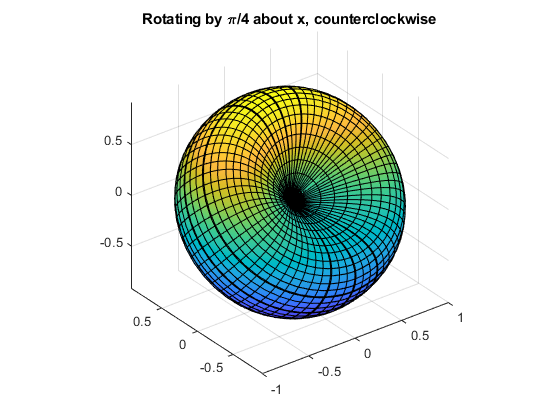

xyzRx = Rx*[x;y;z];
Rx45 = subs(xyzRx, t, pi/4);

fsurf(Rx45(1), Rx45(2), Rx45(3))
title('Rotating by \pi/4 about x, counterclockwise')
daspect([1 1 1]);

Rotate about the `z`-axis by 90 degrees clockwise after the first 45 degree rotation.

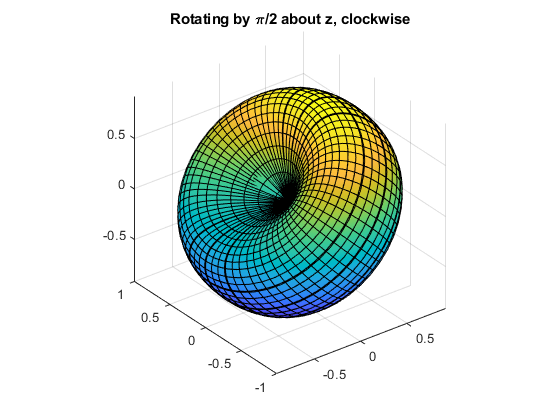

xyzRz = Rz*Rx45;
Rx45Rz90 = subs(xyzRz, t, -pi/2);

fsurf(Rx45Rz90(1), Rx45Rz90(2), Rx45Rz90(3))
title('Rotating by \pi/2 about z, clockwise')
daspect([1 1 1])

Rotate about the `y`-axis by 45 degrees clockwise after the last two rotations.

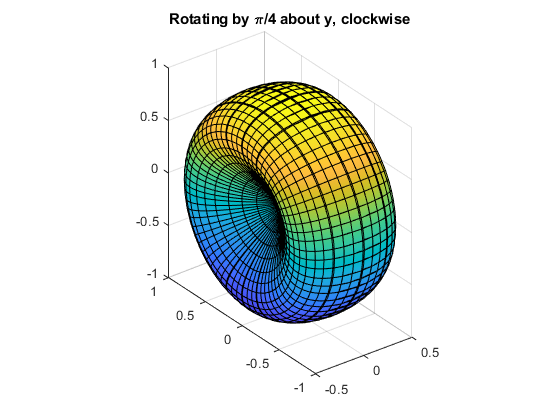

xyzRy = Ry*Rx45Rz90;
Rx45Rz90Ry45 = subs(xyzRy, t, -pi/4);

fsurf(Rx45Rz90Ry45(1), Rx45Rz90Ry45(2), Rx45Rz90Ry45(3))
title('Rotating by \pi/4 about y, clockwise')
daspect([1 1 1])

The [rotate](https://www.mathworks.com/help/matlab/ref/rotate.html) command can rotate a graphical object about a fixed direction by a given angle. Rotate does not accept a parametrized function surface so we have to create a [transform group](http:// https://www.mathworks.com/help/matlab/ref/hgtransform.html) and make our surface a member and then transform that using [makehgtransform](https://www.mathworks.com/help/matlab/ref/makehgtform.html). So we can accomplish the preceding as follows. (See [https://www.mathworks.com/matlabcentral/answers/399602-how-to-rotate-a-fsurf-plot](https://www.mathworks.com/matlabcentral/answers/399602-how-to-rotate-a-fsurf-plot)  and [https://www.mathworks.com/help/matlab/ref/makehgtform.html](https://www.mathworks.com/help/matlab/ref/makehgtform.html) .)

figure

Make some Cartesian axes for the figure to serve as a parent to the surface. Usually, a plotting function call makes these if they don't exist.

ax = axes('XLim',[-1.5 1.5],'YLim',[-1.5 1.5],'ZLim',[-1.5 1.5]);

Make two copies of the surface atop one annother.

hsurf1= fsurf(x,y,z);
hold on
hsurf2 = fsurf(x,y,z+2);
daspect([1 1 1])
xlabel('x');ylabel('y');zlabel('z')

Creat a group of graphic objects. The entire group can be translated or rotated or scaled.

grouphandle = hgtransform('Parent',ax);

Add our surfaces to the group by saying each is a child of the group.

set(hsurf1,'Parent',grouphandle)
set(hsurf2,'Parent',grouphandle)

Now create a group transform matrix. It is 4x4 to accommodate translations as well as rotations.

Rotx45 = makehgtform('axisrotate',[1,0,0],pi/4) 

Rotx45 =     1.0000         0         0         0
         0    0.7071   -0.7071         0
         0    0.7071    0.7071         0
         0         0         0    1.0000


Set the grouphandle's Matrix property to be the rotation matrix. To multiply rotations, create some different 4x4 and set the grouphandle matrix to be that matrix.

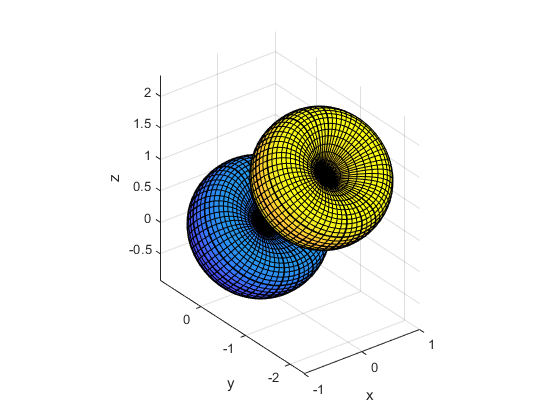

set(grouphandle,'Matrix',Rotx45);
hold off

### Scaling surfaces

Scale the surface by the factor 3 along the `z`-axis. You can multiply the expression for `z` by 3, `z = 3*z`. The more general approach is to create a scaling matrix, and then multiply the scaling matrix by the vector of coordinates.

S = [1 0 0; 0 1 0; 0 0 3];
xyzScaled = S*[x; y; z]

$$xyzScaled = \left(\begin{array}{c} \cos\left(u\right)\,\sin\left(v\right)\\ \sin\left(u\right)\,\sin\left(v\right)\\ 3\,\cos\left(v\right)\,\sin\left(v\right) \end{array}\right)$$

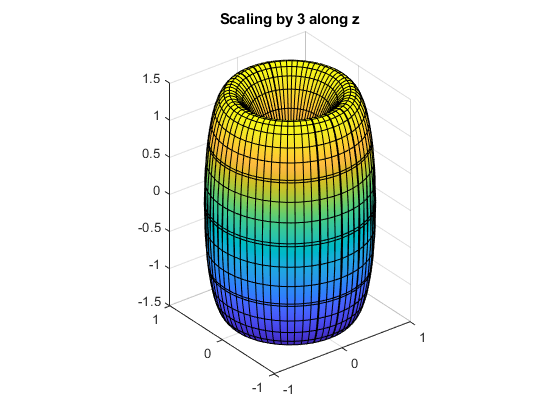

figure
fsurf(xyzScaled(1), xyzScaled(2), xyzScaled(3))
title('Scaling by 3 along z')
daspect([1 1 1])

Rotate the scaled surface about the `x`-, `y`-, and `z`-axis by 45 degrees clockwise, in order `z`, then `y`, then `x`. The rotation matrix for this transformation is as follows.

R = Rx*Ry*Rz

$$R = \begin{array}{l} \left(\begin{array}{ccc} {\cos\left(t\right)}^{2} & -\cos\left(t\right)\,\sin\left(t\right) & \sin\left(t\right)\\ \sigma_{1} & {\cos\left(t\right)}^{2}-{\sin\left(t\right)}^{3} & -\cos\left(t\right)\,\sin\left(t\right)\\ {\sin\left(t\right)}^{2}-{\cos\left(t\right)}^{2}\,\sin\left(t\right) & \sigma_{1} & {\cos\left(t\right)}^{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(t\right)\,{\sin\left(t\right)}^{2}+\cos\left(t\right)\,\sin\left(t\right) \end{array}$$

Use the rotation matrix to find the new coordinates of surface element of the scaled surface.

xyzScaledRotated = R*xyzScaled;
xyzSR45 = subs(xyzScaledRotated, t, -pi/4);

Plot the surface.

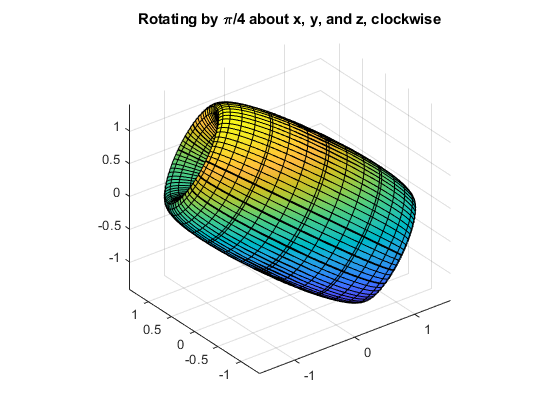

fsurf(xyzSR45(1), xyzSR45(2), xyzSR45(3))
title('Rotating by \pi/4 about x, y, and z, clockwise')
daspect([1 1 1])

**Other parametric surfaces**

syms u v
syms a b c d
a=1;b=1;c=1;d=1;

x = a*v;
y = b*u;
z = u^3-3*u*v^2;

Plot the surface using `fsurf`.

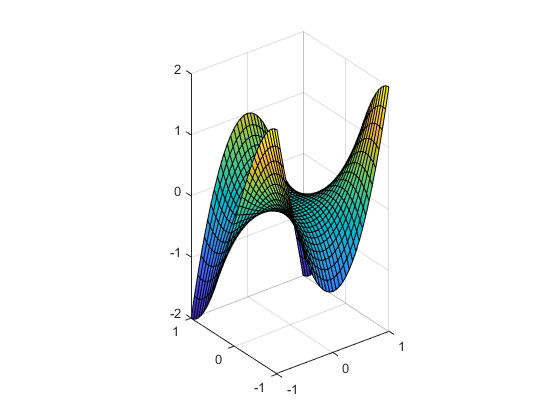

fsurf(x,y,z,[-1,1,-1,1])
daspect([1 1 1])

Show a surface with a contour map superposed.

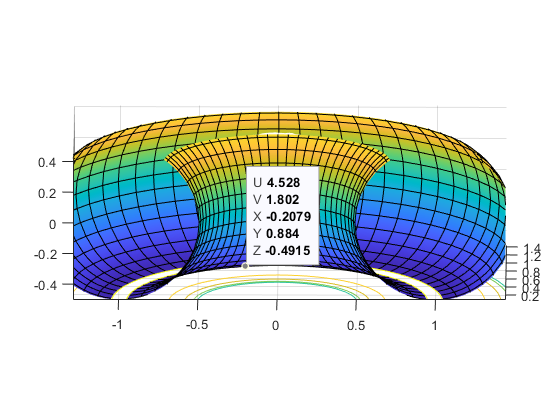

a=1;b=.5;c=b;d=0;
x=(a+b*cos(u))*cos(v);
y=(a+b*cos(u))*sin(v);
z=c*sin(u)+d;
fsurf(x,y,z,[0,2*pi,0,pi],'ShowContours', 'on')
axis equal

***Try this***: Change the limits on the parameters u and v to complete the torus and change the parameters `a`, `b`, `c`, and `d` to change its shape.

The command `fsurf` plots surfaces with x, y ,and z explicitly parametrized. It is also possible to plot surfaces defined implictly with [fimplicit](https://www.mathworks.com/help/matlab/ref/fimplicit.html ). 

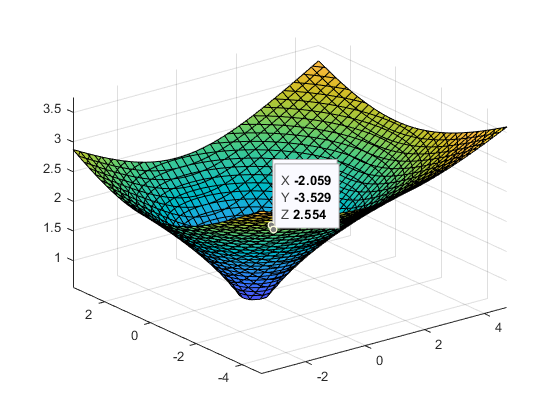

a=1;b=1;c=1;d=3;
f = @(x,y,z) a*x.^2 + b*y.^2 - c*z.^d;
interval = [-5 5 -5 5 0 5];
fimplicit3(f,interval)

A infinite variety of [surfaces ](http:// https://www.mathcurve.com/surfaces.gb/surfaces.shtml )can be defined defined parametrically and implicitly.

A tube is a set of circles with planes orthogonal to the curve of centers. Suppose where ${\bf a}(u)$ is the curve of centers with parameter $u$. Define a unit vector tangent to ${\bf a}$,  $\hat {\bf t}=\dot{\bf a}/|\dot{\bf a}|$, and a unit vector perpendicular to $\hat{\bf t}$, ${\hat{\bf b}=\dot{\bf a}\times{\ddot{\bf a}}/|\dot{\bf a}\times{\ddot{\bf a}}|$. Then ${\hat{\bf n}}={\hat{\bf b}}\times{\hat{\bf t}}$ is a unit vector perpendicular to both $\hat{\bf t}$ and $\hat{\bf b}$. We can write the tube surface as  ${\bf s}(u,v)={\bf a}(u) +r(u)(\cos v~{\hat{\bf n}(u)}+\sin v~\hat{\bf b}(u))$ where $v$ is the angle in the plane of the swept tube circle. Let's visualize a tube.

syms u v real

Make a curve which is the center of a coil wrapped around a planar torus C of center radius R in the x-y plane. The tube radius is r. The parameter u is the azimuth around C. The parameter v is the azimuth around the swept circle of the tube.

r=1;
R=10;
nturns=3; % number of times the coil wraps around the torus
x=cos(u)*(R+4*r*sin(nturns*u));y=sin(u)*(R+4*r*sin(nturns*u));z=4*r*cos(nturns*u);

u0=0;u1=2*pi;v0=0;v1=2*pi;              % limits for the two parameters

a=[x,y,z];dr=diff(a,u);ddr=diff(a,u,2); % curve a and its derivatives
t=dr/sqrt(dr*dr');
b0=cross(dr,ddr);
b=b0/sqrt(b0*b0');
n=cross(b,t);
s=a+r*cos(v)*n+r*b*sin(v);              % 2-parameter surface
figure
fsurf(s(1),s(2),s(3),[u0,u1,v0,v1])
xlabel('x');ylabel('y');zlabel('z');
daspect([1,1,1]);

Add the torus the coil is wrapped around.

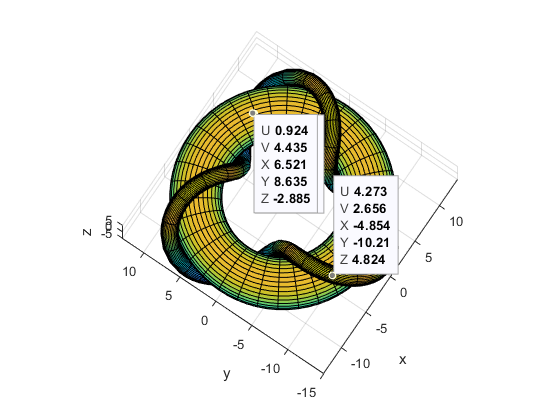

hold on
x=R*cos(u);y=R*sin(u);z=0;r=4-r;
a=[x,y,z];dr=diff(a,u);ddr=diff(a,u,2);
t=dr/sqrt(dr*dr');
b0=cross(dr,ddr);
b=b0/sqrt(b0*b0');
n=cross(b,t);
s=a+r*cos(v)*n+r*b*sin(v);
fsurf(s(1),s(2),s(3),[u0,u1,v0,v1])
hold off

Sweet. Thanks MATLAB!